# Case D - Procesanlæg

clc; clear;



u = symunit;
% Givende værdiger
reg_h_tab = 0.68 * u.m %Fundet fra tabel 4 efter omregning 

$$reg\_h\_tab = \frac{17}{25}\,m$$

psi_butterfly = 1

psi_butterfly = 1

psi_kontra = 2

psi_kontra = 2

g = 9.82 * u.m/u.s^2

$$g = \frac{491}{50}\,\frac{m}{s^{2}}$$

d = linspace(0.01 * u.m, 0.06*u.m,200);
q_V = 0.005 * u.m^3/u.s

$$q\_V = \frac{1}{200}\,\frac{m^{3}}{s}$$

c = vpa(q_V./((pi/4)*(d.^2)))

rho = 998.168 * u.kg/u.m^3

$$rho = \frac{8779978579791315}{8796093022208}\,\frac{\mathrm{kg}}{m^{3}}$$

%Tab
%ventiler
Butterfly_h_tab = psi_butterfly * (c.^2/(2*g));
Kontra_h_tab = psi_kontra * (c.^2/(2*g));

%Indløb
psi_indloeb = 0.5

psi_indloeb = 0.5000

indloeb_h_tab = psi_indloeb * (c.^2/(2*g));

%udløb
psi_indloeb = 1

psi_indloeb = 1

udloeb_h_tab = psi_indloeb * (c.^2/(2*g));

%bøjning
psi_indloeb = 0.3

psi_indloeb = 0.3000

boejning_h_tab = psi_indloeb * (c.^2/(2*g));

%Varmeveksler
veksler_h_tab = unitConvert(unitConvert(0.16 * u.bar, u.Pa) / (rho * g), "SI");


%Tab i rør
%antages en k_s = 0.025
lambda = 0.031 %Figur 4.10

lambda = 0.0310

L(1) = 4 * u.m

$$L = 4\,m$$

hf_roer1 = (lambda * (4 * u.m * c.^2./(d.*2*g)));
L(3) = 10 * u.m

$$L = \left(\begin{array}{ccc} 4\,m & 0 & 10\,m \end{array}\right)$$

hf_roer3 = (lambda * (L(3) .* c.^2./(d.*2*g)));
L(5) = 15 * u.m

$$L = \left(\begin{array}{ccccc} 4\,m & 0 & 10\,m & 0 & 15\,m \end{array}\right)$$

hf_roer5 = lambda * (L(5) .* c.^2./(d.*2*g));

hf_roer = [hf_roer1, zeros(1,200) hf_roer3, zeros(1,200), hf_roer5];

%Kendte højder og forskelle
z(1) = 5 * u.m;
H(1) = z(1);
z(2) = 1 * u.m;
z(3) = 1 * u.m;
z(4) = 7 * u.m;
z(5) = 10 * u.m;

%Forskelle i højder (delta)
Delta_h1 = (z(2) - z(1)) + Butterfly_h_tab + indloeb_h_tab + hf_roer(1);
Delta_h2 = (z(4) - z(2)) + Butterfly_h_tab + boejning_h_tab + hf_roer(3) + Kontra_h_tab;
Delta_h3 = (z(5) - z(4)) + veksler_h_tab + udloeb_h_tab + hf_roer(5) + boejning_h_tab + reg_h_tab;

DeltaH = Delta_h1+Delta_h2+Delta_h3; %Pumpen skal kunne ydde dette. 



Pe = q_V.*rho.*DeltaH.*g/1e3;


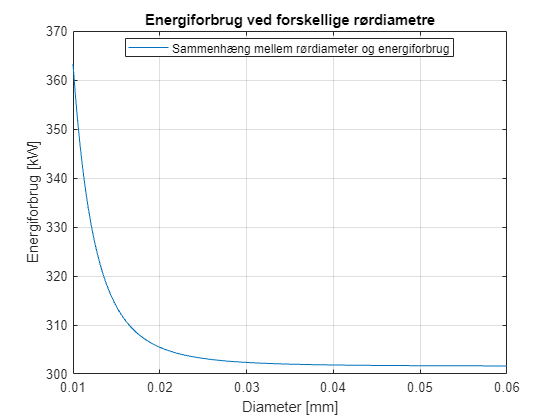



plot(double(separateUnits(d)), double(separateUnits(Pe)))

grid("on")
xlabel("Diameter [mm]")
ylabel("Energiforbrug [kW]")
title("Energiforbrug ved forskellige rørdiametre")
legend("Sammenhæng mellem rørdiameter og energiforbrug","Location","best")